# Matlab第二次大作业

用于从以下电子表格导入数据的脚本:

由 MATLAB 于 2022-12-15 20:51:24 自动生成

## 设置导入选项并导入数据

opts = spreadsheetImportOptions("NumVariables", 61);

% 指定工作表和范围
opts.Sheet = "Sheet1";
opts.DataRange = "A1:BI208";

% 指定列名称和类型
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53", "VarName54", "VarName55", "VarName56", "VarName57", "VarName58", "VarName59", "VarName60", "VarName61"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 导入数据
sonar = readtable("E:\SYSU\2022第一学期\人工智能编程语言\Matlab第二次大作业\sonar.xls", opts, "UseExcel", false);

## 转换为输出类型

sonar = table2array(sonar);

## 清除临时变量

clear opts;
[row,col] = size(sonar);
data = sonar(:,1:col-1);
label = sonar(:,col);
k = 2; % 指定类的数量
[all_acc_list,k_classes_res,vector_cen_list] = My_kmeans(data,label,k)

all_acc_list =     0.5625    0.5144    0.5240    0.5192    0.5337    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433    0.5433


k_classes_res = 2×1 cell 数组
    {[1 1 3 6 8 9 10 11 12 13 16 19 20 21 22 23 25 26 27 28 29 30 31 32 33 34 35 36 37 47 48 49 51 54 55 56 57 60 61 62 67 68 69 70 71 73 74 75 76 77 78 79 80 81 82 83 84 85 86 95 96 97 98 115 116 117 118 119 120 121 122 127 128 129 130 131 132 133 134 135 138 139 140 142 143 144 145 146 148 150 151 152 153 154 170 171 172 173 174 175 176 177 183 184 185 187 188 189 190 193 194 195 196 197 198 199 200 201 202 206 207 208]}
    {[                                                                                                              2 2 4 5 7 14 15 17 18 24 38 39 40 41 42 43 44 45 46 50 52 53 58 59 63 64 65 66 72 87 88 89 90 91 92 93 94 99 100 101 102 103 104 105 106 107 108 109 110 111 112 113 114 123 124 125 126 136 137 141 147 149 155 156 157 158 159 160 161 162 163 164 165 166 167 168 169 178 179 180 181 182 186 191 192 203 204 205]}


vector_cen_list =     0.0283    0.0370    0.0409    0.0477    0.0630    0.0957    0.1125    0.1306    0.1745    0.1975    0.2171    0.2274    0.2316    0.2201    0.2130    0.2442    0.2531    0.2801    0.3382    0.4201    0.4759    0.4974    0.5577    0.6226    0.6543    0.7089    0.7382    0.7750    0.7483    0.6856    0.6008    0.5276    0.5086    0.4937    0.4739    0.4606    0.4196    0.3915    0.3732    0.3454    0.3254    0.3178    0.2788    0.2388    0.2281    0.1872    0.1339    0.1012    0.0550    0.0206
    0.0303    0.0404    0.0479    0.0625    0.0921    0.1169    0.1346    0.1406    0.1829    0.2232    0.2623    0.2820    0.3313    0.4030    0.4693    0.5653    0.6425    0.6918    0.7365    0.7619    0.7943    0.8007    0.7712    0.7423    0.7048    0.6873    0.6520    0.5814    0.4943    0.4354    0.3705    0.3159    0.2901    0.2775    0.2795    0.2795    0.2862    0.2676    0.2599    0.2637    0.2389    0.2234    0.2017    0.1796    0.1543    0.1237    0.1065    0.0778 

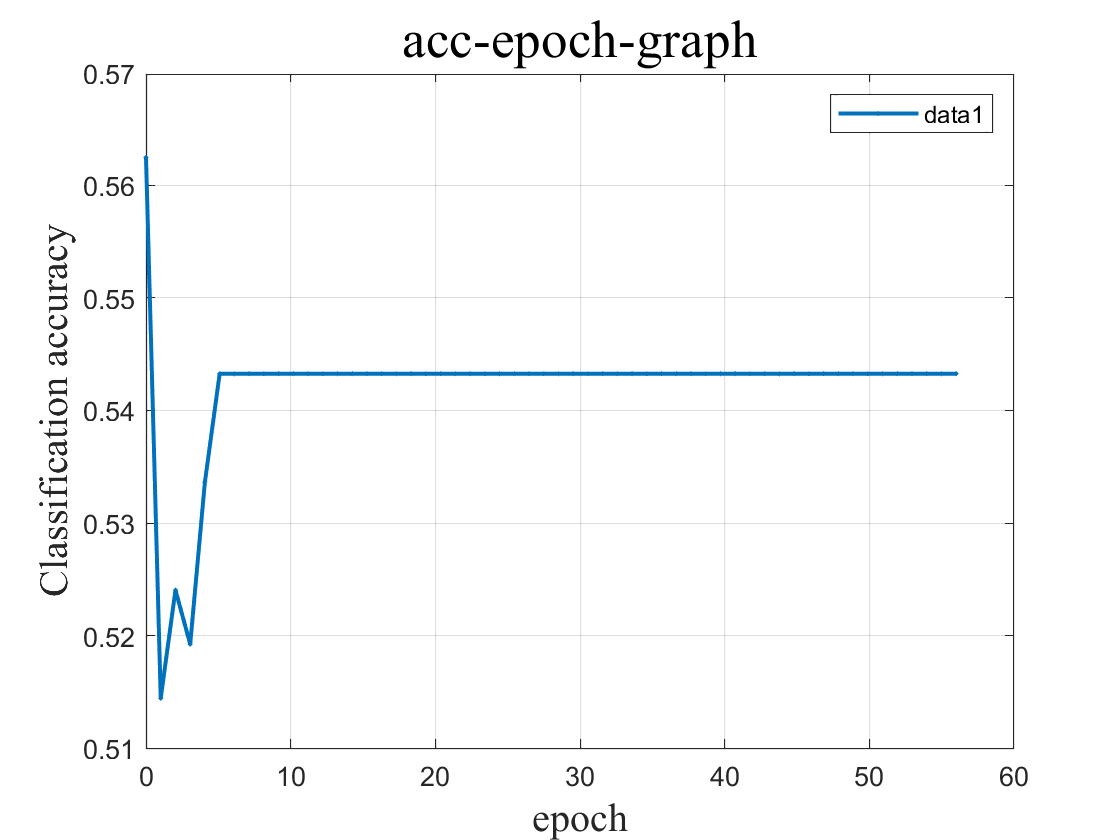

x = linspace(0,length(all_acc_list),length(all_acc_list));
plot(x,all_acc_list,'o-', 'Linewidth', 1.5, 'MarkerSize', 0.5);
title("acc-epoch-graph",'FontName', 'Times New Roman','FontSize', 20); 
xlabel("epoch",'FontName', 'Times New Roman','FontSize', 15); %设置X轴标签
ylabel("Classification accuracy",'FontName', 'Times New Roman','FontSize', 15); %设置Y轴标签title("标题"); %设置标题
grid on;
legend("show")

% idx 表示点的索引
% C 表示每一个类重心的坐标
% 显示聚类结果的代码（直接使用）
% 先把画图要用的idx求出来

% 因聚类图这里画的是二维的，所以我们先用一个pca主成分分析来得出在数据的60个指标中哪两个贡献率最高
R = cov(zscore(data)) % 相关系数矩阵

R =     1.0000    0.7359    0.5715    0.4914    0.3448    0.2389    0.2608    0.3555    0.3534    0.3183    0.3441    0.2109    0.2107    0.2563    0.3049    0.2391    0.1378    0.0418    0.0552    0.1568    0.1177   -0.0570   -0.1634   -0.2181   -0.2957   -0.3429   -0.3417   -0.2243   -0.1991   -0.0774   -0.0484   -0.0304   -0.0319    0.0313    0.0981    0.0807    0.1196    0.2099    0.2084    0.1000    0.1273    0.2136    0.2061    0.1579    0.2800    0.3194    0.2303    0.2032    0.2476    0.2693
    0.7359    1.0000    0.7799    0.6067    0.4197    0.3323    0.2790    0.3346    0.3167    0.2708    0.2971    0.1941    0.2496    0.2732    0.3076    0.2618    0.1522    0.0429    0.0409    0.1024    0.0753   -0.0742   -0.1794   -0.1965   -0.2953   -0.3657   -0.3370   -0.2344   -0.2285   -0.1153   -0.0559   -0.0497   -0.1083   -0.0042    0.1158    0.1326    0.1692    0.2175    0.1868    0.0983    0.1882    0.2613    0.1864    0.1330    0.2857    0.3042    0.2558    0.2653    0.3140    0

corrcoef(data) % 计算相关系数矩阵

ans =     1.0000    0.7359    0.5715    0.4914    0.3448    0.2389    0.2608    0.3555    0.3534    0.3183    0.3441    0.2109    0.2107    0.2563    0.3049    0.2391    0.1378    0.0418    0.0552    0.1568    0.1177   -0.0570   -0.1634   -0.2181   -0.2957   -0.3429   -0.3417   -0.2243   -0.1991   -0.0774   -0.0484   -0.0304   -0.0319    0.0313    0.0981    0.0807    0.1196    0.2099    0.2084    0.1000    0.1273    0.2136    0.2061    0.1579    0.2800    0.3194    0.2303    0.2032    0.2476    0.2693
    0.7359    1.0000    0.7799    0.6067    0.4197    0.3323    0.2790    0.3346    0.3167    0.2708    0.2971    0.1941    0.2496    0.2732    0.3076    0.2618    0.1522    0.0429    0.0409    0.1024    0.0753   -0.0742   -0.1794   -0.1965   -0.2953   -0.3657   -0.3370   -0.2344   -0.2285   -0.1153   -0.0559   -0.0497   -0.1083   -0.0042    0.1158    0.1326    0.1692    0.2175    0.1868    0.0983    0.1882    0.2613    0.1864    0.1330    0.2857    0.3042    0.2558    0.2653    0.3140   

[coeff,latent,explained] = pcacov(R)

coeff =     0.1364    0.1223    0.0160   -0.0140   -0.1356    0.1102   -0.0659   -0.0333   -0.0372    0.2513    0.0979   -0.2426    0.0060    0.1646    0.0366    0.1752    0.2569   -0.1041    0.3320   -0.0342    0.0740    0.0995   -0.0023   -0.0593    0.2156   -0.2871   -0.0935    0.1756    0.1437    0.1666    0.2658   -0.0160    0.2383    0.1327    0.2756   -0.0501   -0.0022   -0.0509    0.1724   -0.1980    0.0380   -0.0096    0.0548    0.0035   -0.0750   -0.0072   -0.0285   -0.0024    0.0254    0.0040
    0.1461    0.1311    0.0167   -0.0610   -0.1698    0.1432   -0.0568   -0.1188   -0.0913    0.2374    0.1216   -0.1875    0.0371    0.0092    0.1626    0.1215    0.2169   -0.0223    0.0429    0.0425    0.1374    0.0648   -0.0735   -0.1384   -0.1765   -0.0827    0.0703   -0.2130    0.0694    0.0285   -0.1621   -0.0357   -0.1929   -0.1406   -0.0703   -0.0356    0.1137    0.3211   -0.2615    0.3567    0.0835    0.0805   -0.2823   -0.0496    0.0487    0.1309    0.0702    0.0175   -0.1034 

latent =    12.2079
   11.3383
    5.1300
    3.4075
    3.0042
    2.4390
    1.9674
    1.8279
    1.5396
    1.4947


explained =    20.3466
   18.8972
    8.5500
    5.6792
    5.0071
    4.0650
    3.2790
    3.0465
    2.5660
    2.4911


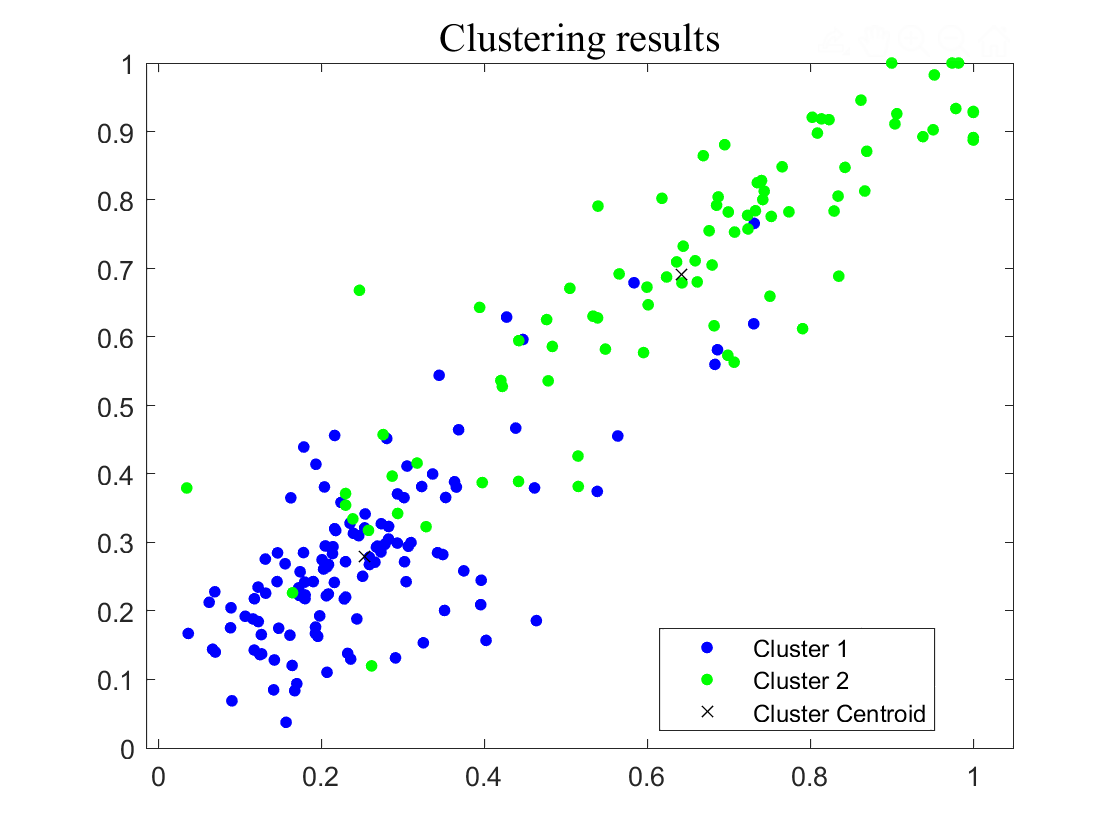

figure
print_col1 = 17;
print_col2 = print_col1 + 1;
idx = get_idx(k_classes_res,length(data));
gscatter(data(:,print_col1),data(:,print_col2),idx,'bgm')
hold on;
plot(vector_cen_list(:,print_col1),vector_cen_list(:,print_col2),'kx')
legend('Cluster 1','Cluster 2','Cluster Centroid')

title("Clustering results",'FontName', 'Times New Roman','FontSize', 15)

function [all_acc_list,k_classes_res,vector_cen_list] = My_kmeans(data,label, k)
    % 先选取k个点作为中心
    vector_cen_list = [];
    all_acc_list = [];
    for i=1:k
        vector_cen_list = [vector_cen_list;data(i,:)];
    end
    % 现在已经选好两个中心点了
    % 现在遍历每一个簇，离vector_cen里面哪个近，就往哪个里面加
    iterator = 50; % 迭代次数
    k_classes_res = []; % 最终分类结果
    while(1)
        % iterator = iterator - 1;
        % k_classes_res是一个二维数组，每一个元素是一个一维数组
        % 这个一维数组的第一个元素表示所分的类，不代表data里面的行号，从第二个元素开始代表行号
        k_classes_res = []; % 存放结果的数组
        for i=1:k
            k_classes_res = [k_classes_res;i];
        end
        k_classes_res = num2cell(k_classes_res); % 转成元胞数组
        for i = 1:length(data) % 遍历每一个簇
            % 此时的向量为
            vector_cur = data(i,:);
            % 计算vector_cur和vector_cen_list[]里面哪个最近
            dis_list = [];
            for j = 1:k
                dis_list = [dis_list,dist(vector_cur,vector_cen_list(j,:))];
            end
            cur_class = find(dis_list == min(dis_list));
            % 此时的cur_class就是预测的类，i就是当前向量的下标
            % 把当前向量的下标添加到k_classes_res里面去
            k_classes_res{cur_class} = [k_classes_res{cur_class},i];
        end
        % 结束这个循环之后
        % 已经分好类了
        % 先算一下acc
        acc = cal_acc(k_classes_res,label);
        all_acc_list = [all_acc_list,acc];
        % disp('d');
        % 现在要更新簇中心
        old_cen_list = vector_cen_list;
        vector_cen_list = [];
        for i=1:k
            vector_cen_list = [vector_cen_list;update_cen_v(data,k_classes_res{i})];
        end
        threshold = 0.0000000001; % 当k个簇的中心和旧的中心距离都小于threshold的时候 -- 重复iterator次后停止循环
        dis_break = [];
        for i = 1:k % 有k个簇中心 -- 重复k次
            dis_break = [dis_break,dist(old_cen_list(i),vector_cen_list(i))];
        end
        if max(dis_break)<threshold
            iterator = iterator - 1;
            if iterator == 0
                break;
            end
        end
    end
end

% 计算欧几里得距离
function dis = dist(v1,v2)
    assert(length(v1)==length(v2));
    len = length(v1);
    dis_sq = 0;
    for i=1:len
        dis_sq = dis_sq + (v1(i)-v2(i))^2;
    end
    dis = sqrt(dis_sq);
end
% 计算acc的函数
function acc = cal_acc(res,label)
    all = length(label);
    bingo_cnt = 0; % 预测对的数量
    for i=1:all
        % 遍历所有的label 看是否预测对了
        if find(res{label(i)} == i)
            bingo_cnt = bingo_cnt + 1;
        end
    end
    acc = bingo_cnt / all;
end
% 更新聚类中心
function new_v = update_cen_v(data,class_res)
    m_tmp = [];
    for i=2:length(class_res)
        idx = class_res(i);
        m_tmp = [m_tmp;data(idx,:)];
    end
    new_v = mean(m_tmp);
end
% 处理聚类结果的函数
function idx = get_idx(k_classes_res,len)   
    idx = zeros(len,1);
    for i = 1:length(k_classes_res)
        v = k_classes_res{i};
        for j = 2:length(v)
            idx(v(j)) = i;
        end
    end
end